# Lecture 9: Loop Shaping PD controller

- Design P controller

- Design PD controller

Consider the active suspension of a car designed to keep the vertical motion of the car frame $y\left(t\right)$ steady.

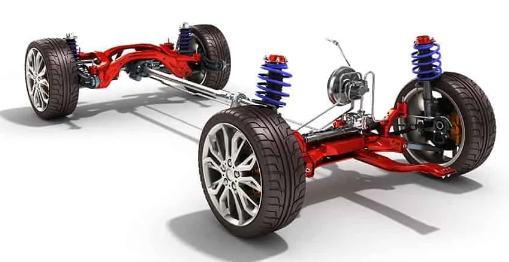

A simple model of this system is a spring mass damper system controlled with a servo force $u\left(t\right)$. The plant for this system is $G\left(s\right)=\frac{1}{{\textrm{ms}}^2 +\textrm{cs}+k}$

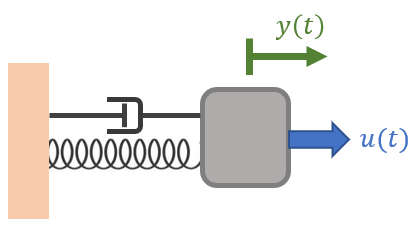

We need to design the controller $C\left(s\right)$ such that the closed-loop system is stable, has a bandwidth of $\omega {\;}_c =6$ rad/s and satisfies the following robustness margins:

- PM $>{30}^o$

- GM $>6$dB

- MM $<6$dB

clc; clear all; close all;

% Plant
s = tf('s');
m = 1;      % Mass [kg]   
c = 1;      % Damping [kg/s]
k = 10;     % Stiffness [N/m]
G = 1/(m*s^2+c*s+k);

% Requirements
w_c = 6;    % Bandwidth [rad/s]
PM_req = 30;    % Phase Margin [deg]
GM_req = 6;     % Gain Margin [dB]
MM_req = 6;     % Modulus Margin [dB]

## P controller

Let's first try a P-controller. Plot the Bode for the open-loop $L\left(s\right)$ when there is just a P controller $C\left(s\right)=P$ is:


$$L\left(s\right)=\textrm{PG}\left(s\right)=\frac{P}{{\textrm{ms}}^2 +\textrm{cs}+k}$$


To meet the bandwidth requirement solve for $|L\left(j\omega_c \right)|=0\textrm{dB}=1$. Hence:


$$1=\left|\textrm{PG}\left(j\omega_c \right)\right|$$



$$P=\frac{1}{|G\left(j\omega_c \right)|}$$


disp('P controller')

P controller


P = 1/abs(evalfr(G,w_c*j))

P = 26.6833


C = P;      % P controller
L = C*G;    % Open loop
margin(L)

nyquist(L)
xlim([-2,0.1])
ylim([-1,1])

Notice that the P controller pushes the gain up so that the system now has a desired bandwidth. The gain margin is $\infty$ which is also great. However, the phase margin is not met. The Nyquist plot shows this as well since the contour is very close to the -1 point. To fix this, we need to add phase at $\omega {\;}_c$.

## PD controller

Now apply a PD controller $C\left(s\right)=P\left(\textrm{Ds}+1\right)$. This is useful because the zero of the controller will add phase. 


$$L\left(s\right)=P\left(\textrm{Ds}+1\right)G\left(s\right)$$


Recall PM is the phase above -180 degrees at the crossover. To meet the PM requirement solve $D$ such that $\angle \;L\left(j\omega {\;}_c \right)=-180+\textrm{PM}$


$$\angle \;P\left(\textrm{Dj}\omega_c +1\right)+\angle G\left(j\omega_c \right)=-180+\textrm{PM}$$



$$\tan^{-1} \left(\frac{\textrm{PD}\omega_c }{P}\right)+\angle G\left(j\omega_c \right)=-180+\textrm{PM}$$



$$D=\frac{1}{\omega_c \;}\tan \left(-180+\textrm{PM}-\angle G\left(j\omega_c \right)\right)$$


To find $P$ solve for $|L\left(j\omega_c \right)|=1$


$$1=\left|P\left(D\omega_c j+1\;\right)G\left(j\omega_c \right)\right|$$



$$P=\frac{1}{|\left(D\omega_c j+1\right)G\left(j\omega_c \right)|}$$


disp('PD controller')

PD controller


D = (1/w_c)*tan(-pi+PM_req*pi/180 - angle(evalfr(G,w_c*j)))

D = 0.0510

P = 1 / abs((D*w_c*j+1)*evalfr(G,w_c*j))

P = 25.5167


C = P*(D*s+1);  % PD controller
L = C*G;        % Open loop
margin(L)

nyquist(L)
xlim([-2,0.1])
ylim([-1,1])

Note that the PD controller creates additional phase at $\omega_c$ which gives us an acceptable PM. The Nyquist plot also shows we're further from -1. But are we far enough? What is the MM?


$$\textrm{MM}=|S|_{\max }$$


S = 1/(1+L);    % Sensitivity
bode(S)
title('Sensitivity')

% Find maximum of S
w = logspace(-1,2,1000);
S_mag = squeeze(abs(freqresp(S,w)));
MM = max(S_mag);
MM = mag2db(MM)

MM = 6.0830

Notice that we just miss the requirement that $\textrm{MM}<6\textrm{dB}$. There are many improvements to be made (eg including a lead filter centered at $\omega_c$). But a quick fix is to increase the P gain a bit to get slightly larger phase at a slightly larger crossover.

disp('Better PD controller')

Better PD controller



% Choose P gain
P = 48

P = 48


% Calculate GM, PM, MM
C = P*(D*s+1);  % PD controller
L = C*G;        % Open loop
margin(L)

S = 1/(1+L);    % Sensitivity
w = logspace(-1,2,100);
S_mag = squeeze(abs(freqresp(S,w)));
MM = max(S_mag);
MM = mag2db(MM)

MM = 5.7677